# Example sync pulse analysis

Move to \synchronization_protocol\Example_data\ 

Add 'synchronization_protocol' and its subfolders to path

Dagher & Ishiyama (2023)

## Extract TTL times from each device

nlxFile = 'Events.nev';
audioFile = 'Audio.wav';
cam1File = 'cam1.csv';
cam2File = 'cam2.csv';

nlxTTLtime = getNlxTTL_demo(nlxFile);
audioTTLtime = getAudioTTL_demo(audioFile);

Extracting Audio TTL...


cam1TTLtime = getVideoTTL_demo(cam1File);
cam2TTLtime = getVideoTTL_demo(cam2File);

% Set first TTL as 0 [s]
nlxTTLtime = nlxTTLtime - nlxTTLtime(1);
audioTTLtime = audioTTLtime - audioTTLtime(1);
cam1TTLtime = cam1TTLtime - cam1TTLtime(1);
cam2TTLtime = cam2TTLtime - cam2TTLtime(1);

## Check pulses

Here we verify the followings across different devices:

- Number of pulses

- Session durations (last pulse time - first pulse time)

- Mean inter-pulse interval

- Max inter-pulse interval

- Min inter-pulse interval

checkPulses(nlxTTLtime, audioTTLtime, cam1TTLtime, cam2TTLtime)

ans = 4×6 table
     Var1      nPulses     durs     meanDiffs    maxDiffs    minDiffs
    _______    _______    ______    _________    ________    ________
    'NLX'        630         629           1      1.0001     0.99998 
    'Audio'      630      629.01           1           1           1 
    'Cam1'       630      628.99     0.99998      1.0001      0.9668 
    'Cam2'       630      628.99     0.99998      1.0001      0.9668 

## Inter-pulse intervals for each device

Unusually small inter-pulse intervals indicate sampling loss.

The periodical apperance of small inter-pulse intervals in the cameras will be explained below.

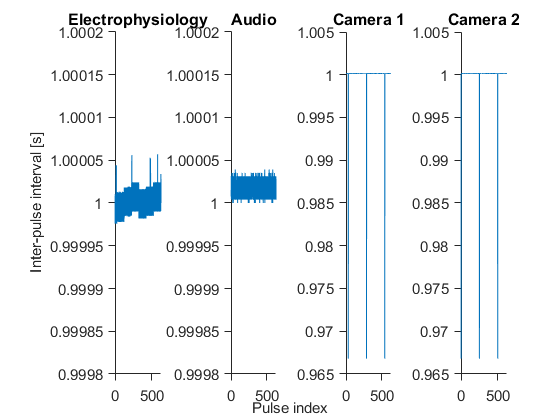

figure
% NLX
subplot(1,4,1);
plot(diff(nlxTTLtime))
beautifyAx(gca)
ylim([0.9998, 1.0002])
title('Electrophysiology')

% Audio
subplot(1,4,2);
plot(diff(audioTTLtime))
beautifyAx(gca)
ylim([0.9998, 1.0002])
title('Audio')

% Cam1
subplot(1,4,3);
plot(diff(cam1TTLtime))
beautifyAx(gca)
title('Camera 1')

% Cam2
subplot(1,4,4);
plot(diff(cam2TTLtime))
beautifyAx(gca)
title('Camera 2')

% empty axis for common labels
h = axes(gcf, 'visible', 'off');
h.XLabel.Visible = 'on';
h.YLabel.Visible = 'on';
xlabel(h, 'Pulse index')
ylabel('Inter-pulse interval [s]')

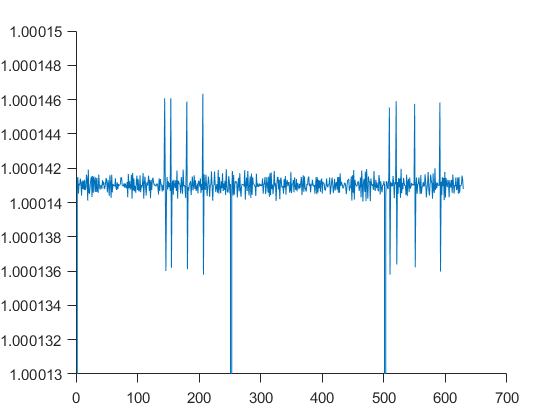

% Zoom in cameras
figure
plot(diff(cam2TTLtime))
beautifyAx(gca)
ylim([1.00013, 1.00015])

## Simulation of clock difference between camera and the pulse generator

Here we simulate the inter-pulse interval artifacts in the cameras

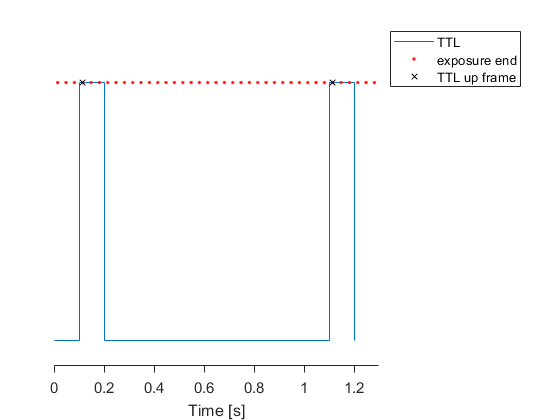

% time in [s]
% 1 Hz sync TTL

isSameClock = false; % play around with this

recDur = 600;
% pulse generator (Teensy)
pulseStart = 0.1;
teensyClock = 1.00;
pulseInterval = 1 * teensyClock;
pulseWidth = 0.1 * teensyClock;
nTTL = round(recDur / pulseInterval);
TTLup = [0:nTTL-1] * pulseInterval + pulseStart;
TTLdown = TTLup + pulseWidth;

allTTLtimes = [TTLup; TTLdown];
allTTLtimes = allTTLtimes(:);
allTTLlogics = repmat([1 0], [1, nTTL]);
if pulseStart > 0
    allTTLtimes = [0; allTTLtimes];
    allTTLlogics = [0, allTTLlogics];
end
showRange = 1.3;

% plot TTL pulses
figure;
p1 = stairs(allTTLtimes(allTTLtimes < showRange), allTTLlogics(allTTLtimes < showRange));
hold on

% camera
camClock = 1.0001; % camera clock is 100 µs slower than Teensy clock
if isSameClock
    camClock = 1; % camera clock is the same as Teensy clock
end
exposureTime = 0.015 * camClock;
framerate = 30;
IFI = 1/framerate * camClock;
nFrames = recDur / IFI;
expEnds = [0:nFrames-1] * IFI + exposureTime; % frame timestamps saved in CSV


% plot frame timestamps
p2 = plot(expEnds(expEnds<showRange)', ones(sum(expEnds<showRange),1), 'r.');

% get TTL state at each exposure end
frameTTL = any(expEnds > TTLup' & expEnds < TTLdown', 1);
TTLupFrames = find(diff(frameTTL) == 1) + 1;
TTLupFrameTime = expEnds(TTLupFrames);

% plot TTL rise frame timestamps 
p3 = plot(TTLupFrameTime(TTLupFrameTime < showRange), ones(sum(TTLupFrameTime<showRange),1), 'kx');
hold off

xlim([0,showRange])
ylim([-0.1,1.2])
legend({'TTL','exposure end', 'TTL up frame'}, 'Location',"bestoutside")
legend
xlabel('Time [s]')
beautifyAx(gca)
ax = gca;
ax.YAxis.Visible = 'off';

The blue line indicates sync TTL state.

Red dots indicate when exposures frames finish, when timestamps and TTL state are collected to save as a CSV file.

Black cross indicate first frame time of given sync TTLs.

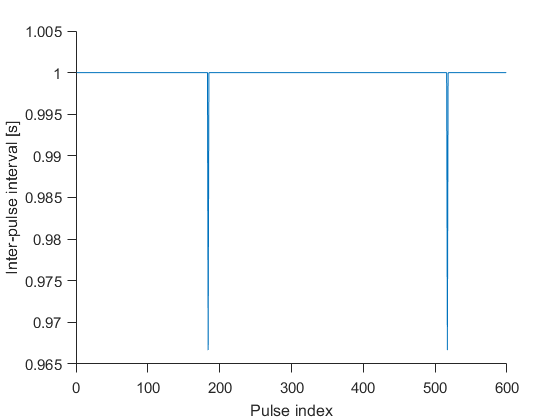

% plot inter-pulse interval in the camera
figure;
plot(diff(TTLupFrames./framerate))
xlabel('Pulse index')
ylabel('Inter-pulse interval [s]')
beautifyAx(gca)

## Normalize duration

nlxDur = nlxTTLtime(end);
normAudioTTL = normDur(audioTTLtime, nlxDur);
normCam1TTL = normDur(cam1TTLtime, nlxDur);
normCam2TTL = normDur(cam2TTLtime, nlxDur);

## Visualize linear drift

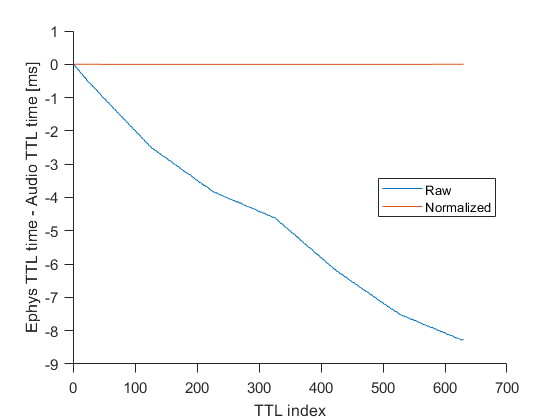

figure
plot((nlxTTLtime - audioTTLtime).*1e3)
beautifyAx(gca)
xlabel('TTL index')
ylabel('Ephys TTL time - Audio TTL time [ms]')
hold on
plot(nlxTTLtime - normAudioTTL)
hold off
legend('Raw', 'Normalized', 'location', 'east')

## Functions

function T = checkPulses(nlxTTLtime, audioTTLtime, cam1TTLtime, cam2TTLtime)
    names = {'NLX', 'Audio', 'Cam1', 'Cam2'};    
    pulses = {nlxTTLtime, audioTTLtime, cam1TTLtime, cam2TTLtime};
    
    durs = cellfun(@(x) x(end) - x(1), pulses)';
    diffs = cellfun(@diff, pulses, 'UniformOutput', false);
    nPulses = cellfun(@numel, pulses)';
    meanDiffs = cellfun(@mean, diffs)';
    maxDiffs = cellfun(@max, diffs)';
    minDiffs = cellfun(@min, diffs)';
    sameN = length(unique(nPulses)) == 1;
    if ~sameN
        warning('Number of pulses are inconsistent')
    end
    T = table(names', nPulses, durs, meanDiffs, maxDiffs, minDiffs);
end

function beautifyAx(ax)
    set(ax, 'Box', 'off', 'TickDir', 'out', 'TickLength', [0.02, 0.02], 'FontSize', 11)
end

function normalized = normDur(ttlTime, dur)
    normalized = ttlTime/ttlTime(end) * dur;
end